clear all 
clc

load test_EsT
load test_GP


save test_GP_two test_GP_two

# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Sep-2021 13:29:24

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([32 32 1],"Name","imageinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],128,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    convolution2dLayer([3 3],256,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],256,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_1","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_1")
    convolution2dLayer([3 3],128,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_9")
    convolution2dLayer([3 3],128,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")
    reluLayer("Name","relu_10")
    transposedConv2dLayer([3 3],64,"Name","transposed-conv_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_2")
    convolution2dLayer([3 3],64,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_12")
    convolution2dLayer([3 3],64,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")
    reluLayer("Name","relu_13")
    convolution2dLayer([1 1],1,"Name","conv_12","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput","conv_1");
lgraph = connectLayers(lgraph,"imageinput","addition/in2");
lgraph = connectLayers(lgraph,"relu_2","maxpool_1");
lgraph = connectLayers(lgraph,"relu_2","concat_2/in1");
lgraph = connectLayers(lgraph,"relu_4","maxpool_2");
lgraph = connectLayers(lgraph,"relu_4","concat_1/in2");
lgraph = connectLayers(lgraph,"relu_8","concat_1/in1");
lgraph = connectLayers(lgraph,"relu_11","concat_2/in2");
lgraph = connectLayers(lgraph,"conv_12","addition/in1");

## Plot Layers

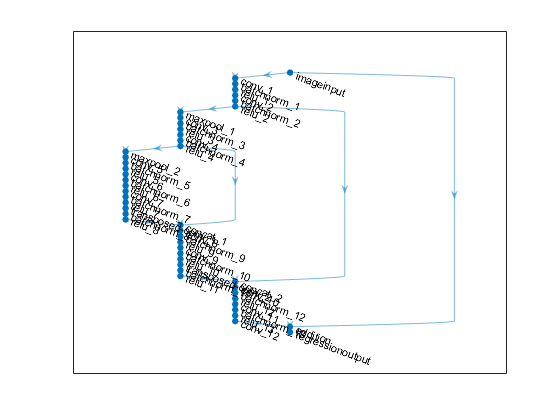

plot(lgraph);


options = trainingOptions('sgdm', ...
    'Momentum', 0.99, ...
    'LearnRateSchedule','piecewise', ...
    "InitialLearnRate",1.0e-4, ...
    'LearnRateDropFactor',0.1, ...
    'L2Regularization',1.0000e-4,...
    'LearnRateDropPeriod',100, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',16, ...
    'Shuffle',"every-epoch",...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9900
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 100
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 200
                   MiniBatchSize: 16
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
              

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |        45.81 |       1049.2 |      1.0000e-04 |
|       1 |          50 |       00:00:08 |         3.10 |          4.8 |      1.0000e-04 |
|       2 |         100 |       00:00:13 |         1.16 |          0.7 |      1.0000e-04 |
|       3 |         150 |       00:00:17 |         0.82 |          0.3 |      1.0000e-04 |
|       3 |         200 |       00:00:21 |         1.30 |          0.8 |      1.0000e-04 |
|       4 |         250 |       00:00:25 |         1.39 |          1.0 |      1.0000e-04 |
|       5 |         300 |  

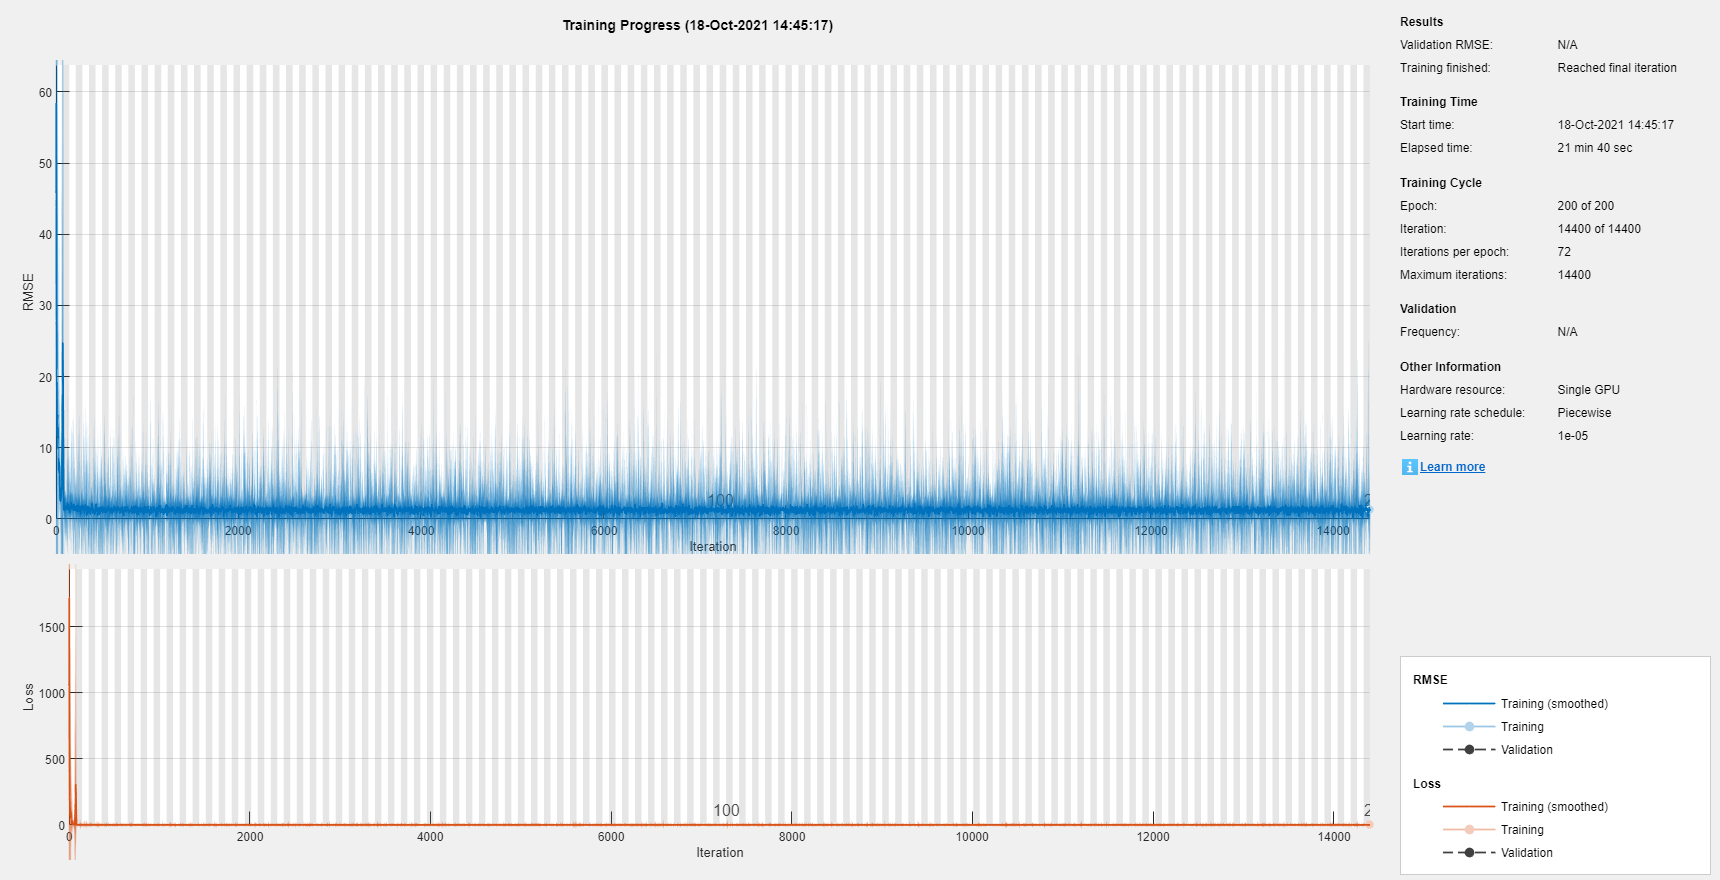

net =   DAGNetwork with properties:

         Layers: [47×1 nnet.cnn.layer.Layer]
    Connections: [49×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}



net = trainNetwork(train_EsT_two,train_GP_two,lgraph,options)

test_EsT_two = predict(net,test_EsT_two);

save test_EsT_two test_EsT_two

